# Clean & Load


clear all
close all
clc
%load('C:\Users\Daniel\Google Drive\Masterarbeit\Camera Measurements\TriangulationMeasurementNew\points.mat')
%load('C:\Users\Daniel\Google Drive\Masterarbeit\Camera Measurements\TriangulationMeasurementNew\distances.mat')
load('points.mat');
load('distances.mat');

## 2D distance Plot

%1-22
f1 = figure(1);
f1.Name = 'Distances';
f1.Units = 'centimeters';
%f1.Position = [5 5 14.35 8.87];
f1.Color = [1 1 1];
f1.Resize='off';

xaxis=[1:1:22];
xaxis(23:44)=[180:1:201];
yaxisdist=resultdist(1,1:44);
stem(xaxis,yaxisdist,'.','Linewidth',1,'Color',[0.6 0.6 0.6]);
xlabel('$Repetitions$','FontName','Helvetica', 'interpreter','latex' ,'FontSize' , 16);
ylabel('$Distance / \mathrm{mm}$', 'interpreter','latex','FontSize' , 16 );

ax1=f1.CurrentAxes;
ax1.YGrid = 'on';
ax1.XGrid = 'on';
ax1.GridLineStyle = ':';
ax1.XLim = [0 202];
xticks([0:5:24 180:5:202]);
ax1.LineWidth = 0.75;
ax1.FontName = 'Helvetica';
ax1.FontSize = 11;
%ax1.XLabel.String = 'rpm';
h = breakxaxis([23 178]);

annotationAxes =   Axes with properties:

             XLim: [0 202]
             YLim: [0 0.1400]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: ':'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


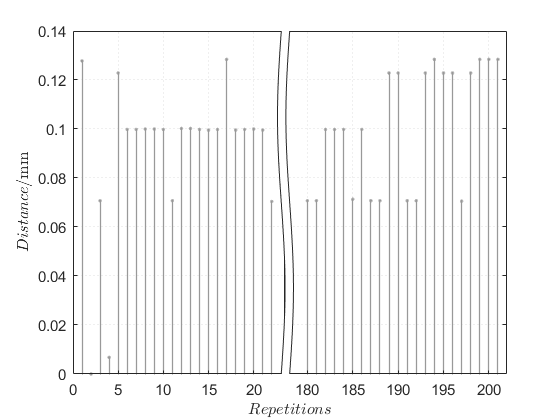

hold off;

## 180-201

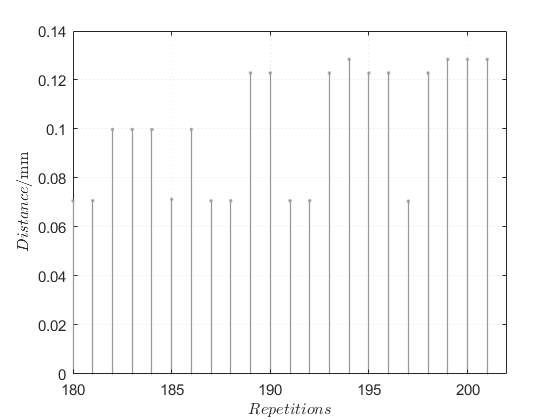

f2 = figure(2);
f2.Name = 'Distances';
f2.Units = 'centimeters';
f2.Color = [1 1 1];
f2.Resize='off';
xaxis=[180:1:201];
yaxisdist=resultdist(1,23:44);
stem(xaxis,yaxisdist,'.','Linewidth',1,'Color',[0.6 0.6 0.6]);
xlabel('$Repetitions$','FontName','Helvetica', 'interpreter','latex' ,'FontSize' , 16);
ylabel('$Distance / \mathrm{mm}$', 'interpreter','latex','FontSize' , 16 );

ax2=f2.CurrentAxes;
ax2.YGrid = 'on';
ax2.XGrid = 'on';
ax2.GridLineStyle = ':';
ax2.XLim = [180 202]; 
ax2.LineWidth = 0.75;
ax2.FontName = 'Helvetica';
ax2.FontSize = 11;

%ax1.XLabel.String = 'rpm';


## 3D Plot

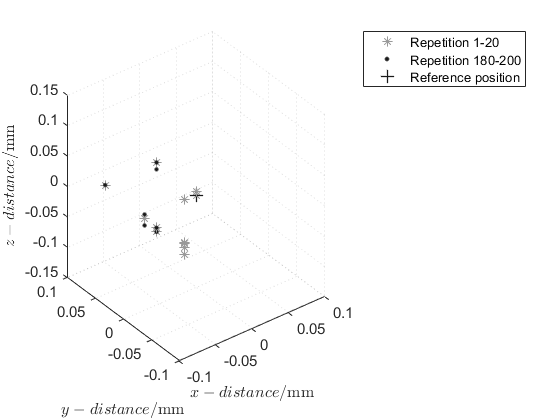


f3=figure(3);
f3.Name = '3D-Position';
f3.Units = 'centimeters';
f3.Resize='off';
%1-20
plot3([resultpoints(1:23,1)],[resultpoints(1:23,2)],[resultpoints(1:23,3)],'*','MarkerSize',7,"LineWidth",0.75,"Color",[0.6 0.6 0.6])
hold on
%180-201
plot3([resultpoints(23:44,1)],[resultpoints(23:44,2)],[resultpoints(23:44,3)],'.','MarkerSize',10,'Color',[0.1 0.1 0.1])
hold on;
%Origin
plot3([resultpoints(2,1)],[resultpoints(2,2)],[resultpoints(2,3)],'+',"LineWidth",1,'MarkerSize',10,'Color',[0.1 0.1 0.1])
grid on
legend([{'Repetition 1-20'},{'Repetition 180-200'},{'Reference position'}]);
axis([-0.1 0.1 -0.1 0.1 -0.15 0.15])
xlabel('$x-distance / \mathrm{mm}$','FontName','Helvetica', 'interpreter','latex' ,'FontSize' , 16);
ylabel('$y-distance / \mathrm{mm}$', 'interpreter','latex','FontSize' , 16 );
zlabel('$z-distance / \mathrm{mm}$', 'interpreter','latex','FontSize' , 16 );
ax3=f3.CurrentAxes;
ax3.YGrid = 'on';
ax3.XGrid = 'on';
ax3.XTick = [-0.1:0.05:0.1];
ax3.YTick = [-0.1:0.05:0.1];
ax3.ZTick = [-0.15:0.05:0.15];
ax3.GridLineStyle = ':';
ax3.LineWidth = 0.75;
ax3.FontName = 'Helvetica';
ax3.FontSize = 11;

## template


% 
%     figure
%     plot(t,y,'Linewidth',1,'Color',[0.7 0.7 0.7]);
%     hold on;
%     legend('Data','Over damped PT2', 'interpreter','latex' ,...
%         'FontSize',16,'Location','northeast');
%     plot(t,PT2_over(p_over,t),'Linewidth',1,'Color','black');
%     xlabel('$t / \mathrm{s}$', 'interpreter','latex' ,'FontSize' , 16 ) 
%     ylabel('$d / \mathrm{cm}$', 'interpreter','latex','FontSize' , 16 )
%     hold off;
%     
%     
%     
%     
%     
% f8 = figure;
% f8.Name = 'Order tracking';
% f8.Units = 'centimeters';
% f8.Position = [5 5 14.35 8.87];
% f8.Color = [1 1 1];
% f8.Resize='off';
% 
% po1_LoNoCr = plot(rpm,o1_LoNoCr,'-','Color',[0 0 0],...
%                       'Linewidth',1.0);
% hold on;
% po2_LoNoCr = plot(rpm,o2_LoNoCr,'--','Color',[0 0 0],...
%                       'Linewidth',1.0);
% po3_LoNoCr = plot(rpm,o3_LoNoCr,'-.','Color',[0 0 0],...
%                       'Linewidth',1.0);
% po1_LoCr = plot(rpm,o1_LoCr,'-','Color',[0.7 0.7 0.7],...
%                       'Linewidth',1.0);
% po2_LoCr = plot(rpm,o2_LoCr,'--','Color',[0.7 0.7 0.7],...
%                       'Linewidth',1.0);
% po3_LoCr = plot(rpm,o3_LoCr,'-.','Color',[0.7 0.7 0.7],...
%                       'Linewidth',1.0);
% 
% ax8 = f8.CurrentAxes;
% ax8.Box = 'off';
% ax8.LineWidth = 0.75;
% ax8.FontName = 'Helvetica';
% ax8.FontSize = 11;
% ax8.Units = 'centimeters';
% ax8.OuterPosition = [0 0 14.35 8.87];
% ax8.XGrid = 'on';
% ax3.XTick = [2.5:2.5:15];
% ax8.GridLineStyle = ':';
% ax8.XLim = [5*60 25*60]; 
% ax8.XLabel.String = 'rpm';
% ax8.YGrid = 'on';
% %ax8.YLim = [0 0.22];
% %ax8.YTick = [];
% ax8.YLabel.String = '\it{M} / V';


